# Building Regression Models

## 1. Linear Regression Models

Which of these is NOT a linear regression model? (5, 6)


$$\begin{array}{l}
1\ldotp \;y=a+\textrm{bx}+cx^2 \\
2\ldotp \;y=ax_1 +{\textrm{bx}}_2 +{\textrm{cx}}_3 \\
3\ldotp \;y=ax_1 x_2 +bx_2 x_3 +cx_1 x_3 \\
4\ldotp \;y=a+\textrm{bsin}\left(x_1 \right)+\textrm{csin}\left(x_2 \right)\\
5\ldotp \;y=a+\textrm{bsin}\left(\textrm{cx}\right)-\textrm{c1}*\textrm{c2}\;\textrm{is}\;\textrm{not}\;\textrm{linear}\;\left(\;\textrm{coefficient}\;\textrm{complex}\;\textrm{is}\;\textrm{not}\;\textrm{linear}\right)\\
6\ldotp \;y=a+\textrm{bx}+x^c -a,b,{\textrm{can}}^{\prime } t\;
\end{array}$$


*Note: Models with products of predictor variables may still be linear in the fit coefficients. However, products of coefficients are not considered linear. Also, taking the power of a predictor to the power of a coefficient will be nonlinear.*

### Course Example: Fuel Economy

Load fuel economy data and view the relationships between the numeric predictors and response.

load carEcon
carData

carData = 2587×15 table
    Car_Truck    EngDisp    RatedHP    Transmission    Drive    Weight    Comp    AxleRatio    EVSpeedRatio    AC    PRP    FuelType    City_Highway    Valves_Cyl    FuelEcon
    _________    _______    _______    ____________    _____    ______    ____    _________    ____________    __    ___    ________    ____________    __________    ________

       car       1.4912        76           AV           F      1474.2      13      4.11           25.7        N     1         23         city              4          3.5318 
       car       1.3437       110           AV           F      1417.5    10.8      4.94           29.1        N     31        61         highway           4          3.6187 
       car       1.4912        76           AV           F      1474.2      13      4.11           25.7        N     1         23         highway           4          3.6299 
       car       1.3437       110           AV           F      1417.5    10.8      4.94           2

### 1.1. Fit a single predictor linear model of fuel economy

Fit a single predictor linear model

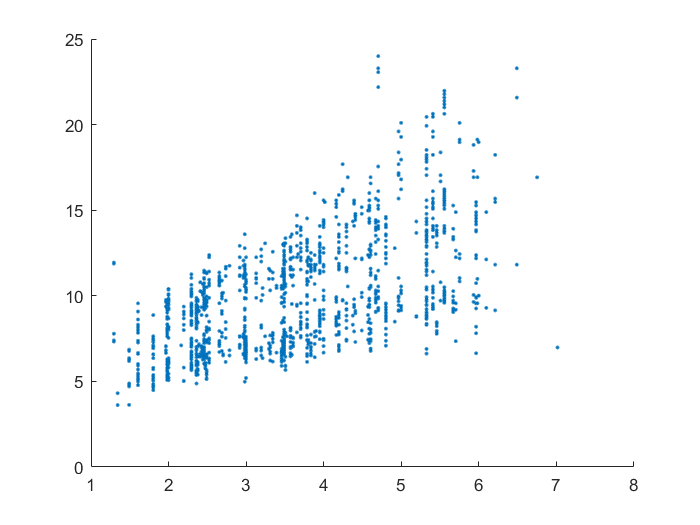

figure
scatter(carTrain.EngDisp,carTrain.FuelEcon,'.')

mdl = fitlm(carTrain(:,{'EngDisp','FuelEcon'}))

mdl = 선형 회귀 모델:
    FuelEcon ~ 1 + EngDisp

추정된 계수:
                   Estimate       SE       tStat       pValue   
                   ________    ________    ______    ___________

    (Intercept)     3.9506       0.2075    19.039     5.4916e-73
    EngDisp         1.6591     0.054062    30.689    6.2992e-163


관측값 개수: 1597, 오차 자유도: 1595
RMS 오차: 2.67
결정계수: 0.371, 수정된 결정계수: 0.371
상수 모델에 대한 F-통계량: 942, p-값 = 6.3e-163

Predict fuel economy for the test data and compare the result with the actual fuel economy of the test data.

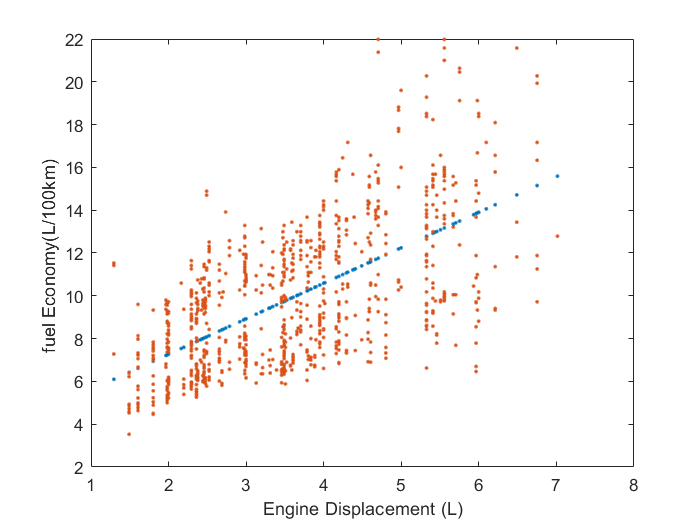

econPred = predict(mdl,carTest.EngDisp);

figure
plot(carTest.EngDisp,econPred,'.')
hold on
scatter(carTest.EngDisp,carTest.FuelEcon,'.')
xlabel('Engine Displacement (L)')
ylabel('fuel Economy(L/100km) ')

Plot distribution of errors

figure
err = carTest.FuelEcon - econPred;
histogram(err)
MSE = mean(err.^2)

MSE = 6.7805

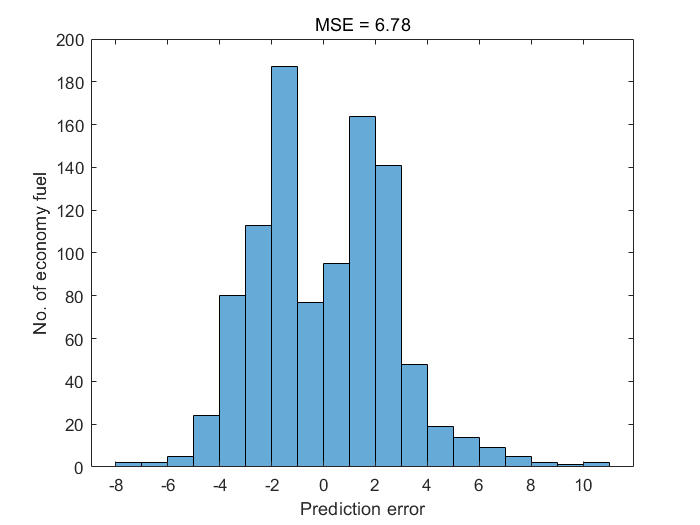

xlabel('Prediction error')
ylabel('No. of economy fuel')
title(['MSE = ',num2str(MSE,4)])

Plot ditribution of percentage errors

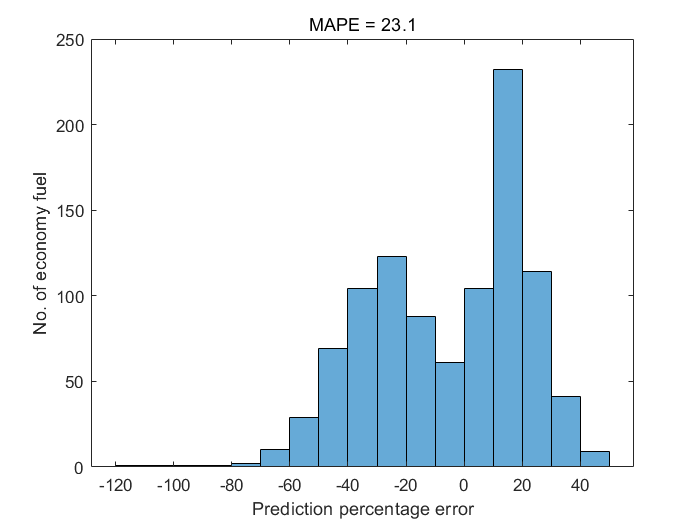

figure
percErr = 100 * err./carTest.FuelEcon;
histogram(percErr)
MAPE=mean(abs(percErr));
xlabel('Prediction percentage error')
ylabel('No. of economy fuel')
title(['MAPE = ',num2str(MAPE,4)])

### 1.2. Fit a two-predictor linear model of fuel economy

NOTE!! When you use `fitlm`, use a table data type rather than an array data type. Because it is much easier to use `'modelspec'` option with a table data type.

For input format in `'modelspec'`, see *Wilkinson-Rogers* notation.

doc wilkinson notation

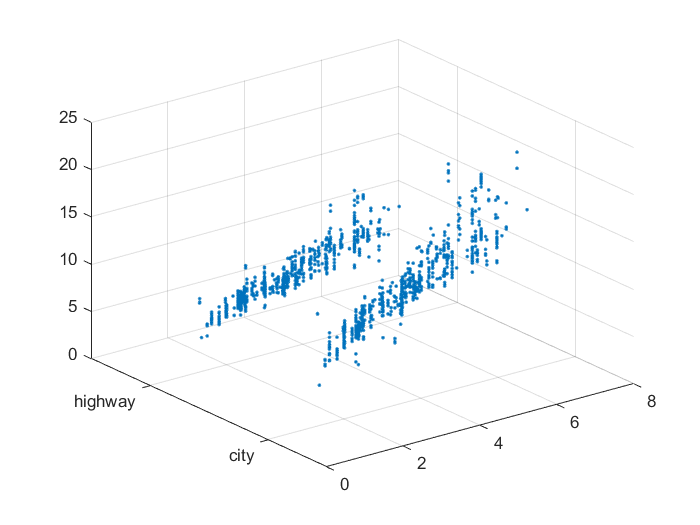

figure
scatter3(carTrain.EngDisp,carTrain.City_Highway,carTrain.FuelEcon,'.')

mdl = fitlm(carTrain(:,{'EngDisp','City_Highway','FuelEcon'}))

mdl = 선형 회귀 모델:
    FuelEcon ~ 1 + EngDisp + City_Highway

추정된 계수:
                            Estimate       SE        tStat       pValue   
                            ________    ________    _______    ___________

    (Intercept)              6.0877      0.12745     47.765    7.9475e-310
    EngDisp                  1.6694     0.031644     52.754              0
    City_Highway_highway    -4.3246     0.078159    -55.331              0


관측값 개수: 1597, 오차 자유도: 1594
RMS 오차: 1.56
결정계수: 0.785, 수정된 결정계수: 0.784
상수 모델에 대한 F-통계량: 2.91e+03, p-값 = 0

Predict fuel economy for the test data and compare the result with the actual fuel economy of the test data.

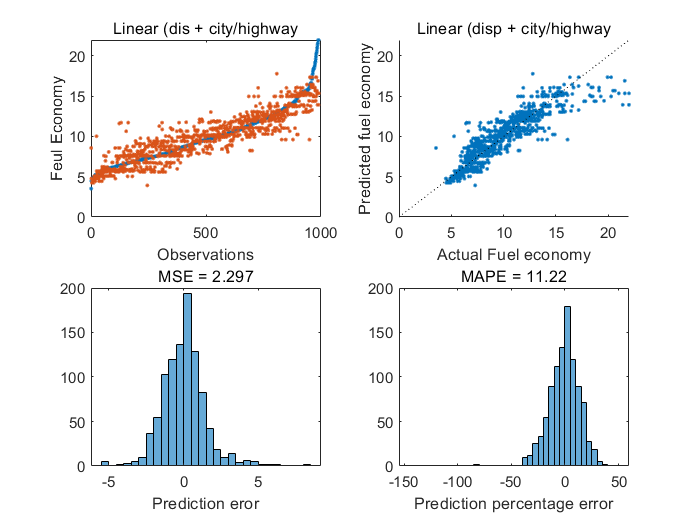

econPred = predict(mdl,carTest(:,{'EngDisp','City_Highway'}));

figure
subplot(2,2,1)
plot(carTest.FuelEcon,'.')
hold on
plot(econPred,'.')
title('Linear (dis + city/highway')
xlabel('Observations')
ylabel('Feul Economy')

subplot(2,2,2)
scatter(carTest.FuelEcon,econPred,'.')

xlimt = xlim;
hold on
plot(xlimt,xlimt,'k')
title('Linear (disp + city/highway')
xlabel('Actual Fuel economy')
ylabel('Predicted fuel economy')

subplot(2,2,3)
err = carTest.FuelEcon - econPred;
histogram(err)
MSE = mean(err.^2);
xlabel('Prediction eror')
title(['MSE = ',num2str(MSE,4)])

subplot(2,2,4)
percErr = 100 * err./carTest.FuelEcon;
histogram(percErr)
MAPE = mean(abs(percErr));
xlabel('Prediction percentage error')
title(['MAPE = ',num2str(MAPE,4)])

### 1.3. Fit a multivariate linear model of fuel economy

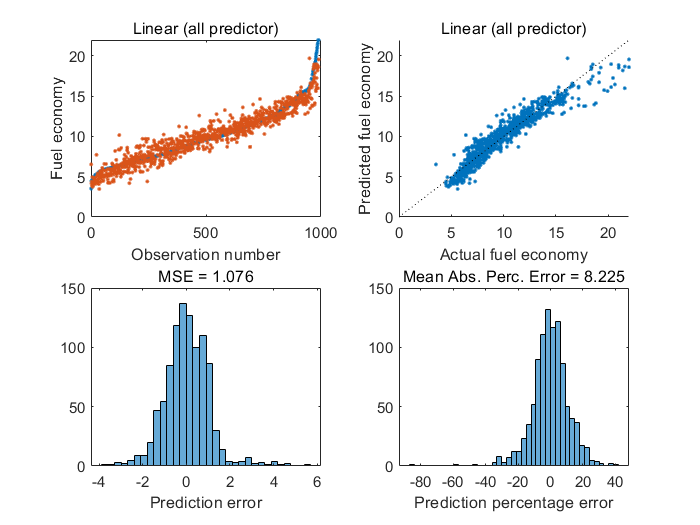

mdl = fitlm(carTrain);
econpred = predict(mdl,carTest);
evaluatefit(carTest.FuelEcon,econpred,'Linear (all predictor)')

Specify the 'RobustOpts' option to reduce the influence of outliers

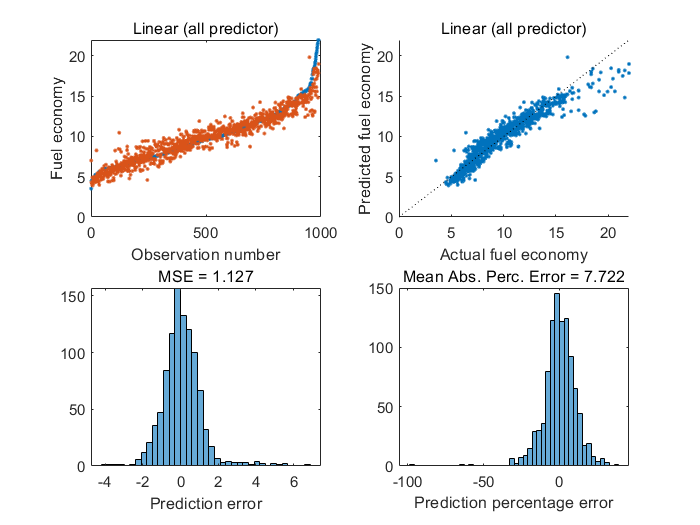

mdl = fitlm(carTrain,'RobustOpts',"cauchy");
econpred = predict(mdl,carTest);
evaluatefit(carTest.FuelEcon,econpred,'Linear (all predictor)')

## 2. Stepwise Fitting

'Stepwise Fitting' is similar with 'Sequential Feature Selection' but provides a simpler interface.

- Sequential Feature Selection : Data + evaluation function

- Stepwise fitting: Data + Criterion( sse(default), aic, bic, rsquared, adjrsquared )

Perform a stepwise linear fit of fuel economy

mdl = stepwiselm(carTrain);

1. City_Highway, FStat = 1103.1943, pValue = 2.6005394e-184 추가
2. EngDisp, FStat = 2783.0129, pValue = 0 추가
3. FuelType, FStat = 84.721, pValue = 8.03591e-105 추가
4. EngDisp:City_Highway, FStat = 347.5023, pValue = 2.768531e-70 추가
5. Drive, FStat = 136.4937, pValue = 2.038924e-55 추가
6. Transmission, FStat = 14.0464, pValue = 4.80023e-36 추가
7. Weight, FStat = 277.8036, pValue = 1.508394e-57 추가
8. Valves_Cyl, FStat = 123.5276, pValue = 1.123981e-27 추가


Predict fuel economy for the test data and compare the result with the actual fuel economy of the test data.

econpred = predict(mdl,carTest);
evaluatefit(carTest.FuelEcon,econpred,'Stepwise')

Change criterion and limit to linear models

mdl = stepwiselm(carTrain,'criterion','aic','Upper','interaction');
econpred = predict(mdl,carTest);
evaluatefit(carTest.FuelEcon,econpred,'Stepwise with aic')

You can also use Sequential Feature Selection which provides a better result but be careful of running this section because it takes long time.

%rng(1234)
%part = cvpartition(carData.FuelEcon,'KFold',10);
%[carDataNum, carDataNum_names] = cattable2mat(carData);

Sequential feature selection on a Multiclass SVM.

%rng(1234)
%error = @(Xtrain , ytrain , Xtest , ytest)...
%    nnz(predict(fitcecoc(Xtrain , ytrain),Xtest)~= ytest);
%tokeep_nb = sequentialfs(error,carDataNum,carData.FuelEcon,'cv',part)

%SelectedPreditors = carDataNum(:,tokkep_nb);
%carDatNum_names(tokeep_nb);
%mdlSelected = fitcecoc(SelectedPreditors,carData.FuelEcon,'CVPartition',part);
%SelectedDataLoss = kfoldLoss(mdlSelected)

Callback function: errorECOC function returns the number of inaccurate predictions for `ytest` by a multiclass SVM classifier.

% function error = errorECOC(Xtrain,ytrain,Xtest,ytest)
% mdlnb = fitcecoc(Xtrain,ytrain);
% ypred = predict(mdlnb,Xtest);
% error = nnz(ypred ~= ytest);
% end